# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**February 17, 2025**

# PART 2 - Design of a Controller for an Underdamped System 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure 

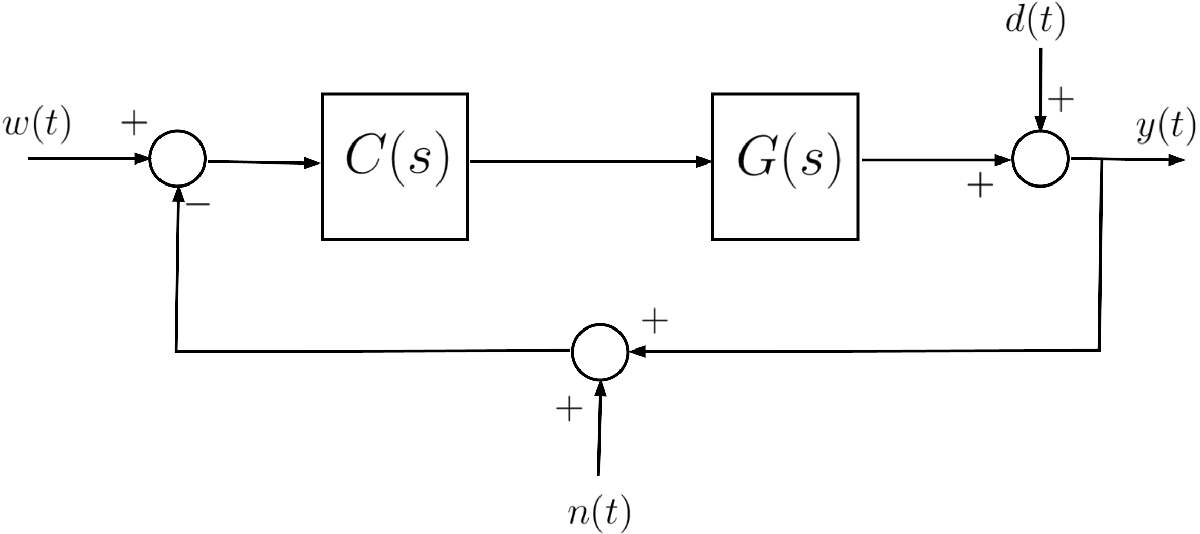	

where $G(s)$ is given by :              


$$G(s) = \displaystyle 4\cdot \frac{\left(1+\displaystyle \frac{1}{2}\,s \right)}{\left(1+\displaystyle \frac{1}{345}\,s + \displaystyle \frac{1}{16}\,s^2\right)\,\left(1+\displaystyle \frac{1}{42}\,s \right)$$
			

Moreover, assume:


$$d(t) \equiv 0 \; \forall t\;,\qquad n(t) \equiv 0 \; \forall t$$


### Assignment 		

**A1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $|e(\infty)| = 0$ for $w(t) = \mathbf{1}(t)$;

- The crossover angular frequency satisfies the constraint:  $20\;\text{rad/s} \le\omega_c \le 30\;\text{rad/s}$; 

- The phase margin satisfies the constraint: $50^{\degree} \le \varphi_m \le 80^{\degree}$.

As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$ 

clear

addpath(genpath('BodeDiagram/'))

s=tf('s');

Gs = 4*(1+(1/2)*s)/((1+(1/345)*s+(1/16)*s^2)*(1+(1/42)*s));

Consideriamo il controllore $\;C_1 =K\frac{\mu_C }{s}$ per soddisfare $\left\vert e(\infty) \right\vert = 0$ per $w(t) = \mathbf{1}(t)$. Infatti aggiungendo un polo nell'origine saremo certi che l'errore statico per w(t)=1(t) sarà nullo.

Per il punto 2. la specifica da aggiungere sarà semplicemente $\omega_c\in\left[20, 30\right]\text{ rad/s}$ sempre, visto che non ci sono vincoli su $d(t)$ o su $n(t)$.

 Per ora inizializzo $\;\mu_C =\frac{s+10}{s+40}$  e $K=50$ che sono valori che dovrebbero funzionare, in caso lo modificherò in seguito.

Progetto C in questo modo per soddisfare i requisiti: infatti avremo K (guadagno) che servirà per ottenere una frequenza $\omega_C$ corretta, mentre per regolare la fase avremo zeri e poli (zero in -10 e polo in -40 se usiamo questa cnofigurazione) che regoleranno il margine di fase.

%muC = (s+10)/(s+40);
%K = 50;
%Cs = K*(muC/s);
muC = 1

muC = 1

%con muC = 0.75 guadagno un po' di margine di fase ma 1 va bene
Cs=muC*(1+s)/s


Cs =
 
  1
  -
  s
 
Continuous-time transfer function.


Ls = Cs * Gs


Ls =
 
                    2 s + 4
  --------------------------------------------
  0.001488 s^4 + 0.06257 s^3 + 0.02671 s^2 + s
 
Continuous-time transfer function.


controlSystemDesigner(Gs, Cs)